# Proyecto Control - IE-0431: Sistemas de Control

## Determinación de controladores

### Grupo 1-7

- Diego Alfaro Segura (C20259)

- Edgar Alvarado Taleno (C10351)

- Jose Flores Quirós ( B82994)

clc
clear
close all

s = tf('s');
Ts = 0.005;
z = tf('z',Ts);

## Modelos escogidos

Temperatura

temp_K = 0.59718;
temp_Tp1 = 27.915;
temp_Tp2 = 2.5594;
temp_G = temp_K/((1+temp_Tp1 *s)*(1+temp_Tp2 *s));

Flujo

fluj_K = 1.1902;
fluj_Tp1 = 0.9887;
fluj_Td = 0.1658;
fluj_G = fluj_K*(exp(-fluj_Td*s))/(1+fluj_Tp1*s);

## Diseño de controladores

#### Proceso de temperatura

Con síntesis

% Factor de ajuste
temp_tauC = 1;

% Valores de controlador
temp_Kp = 1/(temp_K*temp_tauC);
temp_Ti = temp_Tp1;

% Función de controlador
temp_PIstandar_Sintesis = temp_Kp*(1+1/(temp_Ti*s));

Sintonización con PID tuner

% Por si se quiere ver el base de pidtuner
%temp_CPIDtun = pidtune(temp_G, 'PI')
%pidTuner(temp_G)

% Parametros de PIDTune para el controlador 
temp_Kptun =2.562;
temp_Kitun =0.169;
 
% Función de transferencia para el controlador PI
temp_CtunPID = temp_Kptun + temp_Kitun*(1/s);

Sintonización de controlador discreto

% Modelo discreto de temperatura
ERPtemp = c2d(temp_G,Ts,'ZOH');

% Parametros
temp_discreto_Kp = 3.1409;
temp_discreto_Ki = 0.0005;

% Función de controlador
temp_controladorDiscreto = ((temp_discreto_Kp + temp_discreto_Ki)*z - temp_discreto_Kp)/(z-1);

#### Proceso de flujo

Sintonización con Usort1, PI, Ms = 1.6

% Parámetros de la planta 
T0 = fluj_Td/fluj_Tp1;

% Parámetros para PI, Ms = 1.6
a0 = 0.209;
a1 = 0.417;
a2 = -1.064;
b0 = 14.650;
b1 = 8.450;
b2 = 0;
b3 = 15.740;

% Valores de controlador
fluj_Kp = (a0 + a1*T0^a2)/fluj_K;
fluj_Ti = fluj_Tp1*(b0 + b1*T0 + b2*T0^2)/(b3 +T0);

% Función de controlador
fluj_PIstandar_Usort = fluj_Kp*(1+1/(fluj_Ti*s));

Sintonización con *Hay (1998) *

% Parámetros del método de sintonización
fluj_tauMTm = fluj_Td/fluj_Tp1;
fluj_x1 = 3;
fluj_x2 = 5.4;

% Valores del controlador
fluj_Kp_inv = fluj_x1/fluj_K;
fluj_Ti_inv = fluj_x2*fluj_Td;

% Función de controlador
fluj_PIstandar_Hay = fluj_Kp_inv*(1+1/(fluj_Ti_inv*s));

Sintonización con controlador discreto

% Modelo discreto de flujo
ERPfluj = c2d(fluj_G,Ts,'ZOH');

% Controlador obtenido con sisotool
fluj_ganancia_discreto = 0.88437;
fluj_a = -0.9943;

fluj_discreto_Kp = -fluj_ganancia_discreto*fluj_a;
fluj_discreto_Ki = fluj_ganancia_discreto - fluj_discreto_Kp;

% Función de controlador
fluj_controladorDiscreto = ((fluj_discreto_Kp + fluj_discreto_Ki)*z - fluj_discreto_Kp)/(z-1);

## Simulación de controladores

Proceso de temperatura

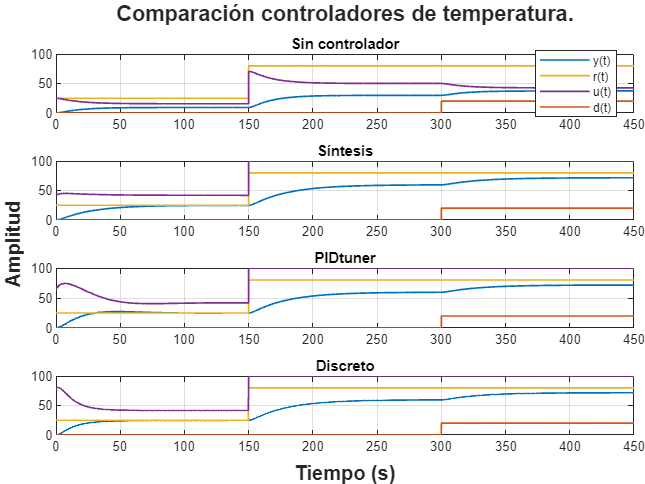

% Mostrar las gráficas
rangoServo = [0, 149];
rangoRegulador = [301, 450];
temp_comparacion = tiledlayout(4, 1, 'TileSpacing', 'compact', 'Padding', 'tight');

ax1 = nexttile;
mostrar_simulacion(tf(1, 1), 450, 'simulinkTemp.slx', 'Sin controlador', ax1, 0, rangoServo, rangoRegulador)

ax2 = nexttile;
mostrar_simulacion(temp_PIstandar_Sintesis, 450, 'simulinkTemp.slx', 'Síntesis', ax2, 0, rangoServo, rangoRegulador)

ax3 = nexttile;
mostrar_simulacion(temp_CtunPID, 450, 'simulinkTemp.slx', 'PIDtuner', ax3, 0, rangoServo, rangoRegulador)

ax4 = nexttile;
mostrar_simulacion(temp_controladorDiscreto, 450, 'simulinkTemp.slx', 'Discreto', ax4, 0, rangoServo, rangoRegulador)

sgtitle(temp_comparacion, 'Comparación controladores de temperatura.', 'FontWeight', 'bold');
xlabel(temp_comparacion, 'Tiempo (s)', 'FontWeight', 'bold')
ylabel(temp_comparacion, 'Amplitud', 'FontWeight', 'bold')

Proceso de flujo

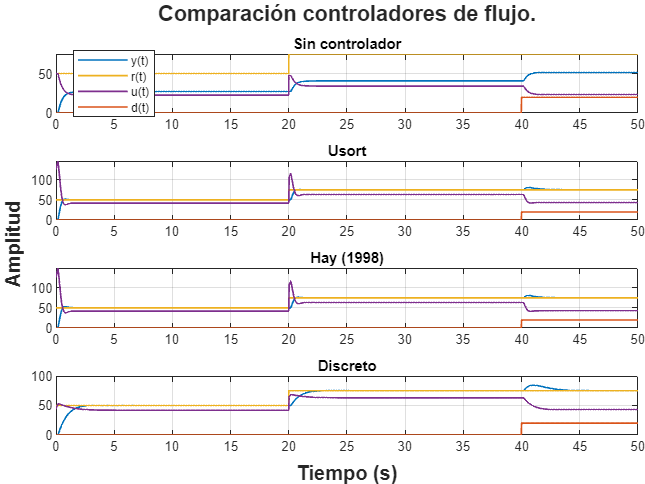

rangoServo = [0, 20];
rangoRegulador = [40, 50];

fluj_comparacion = tiledlayout(4, 1, 'TileSpacing', 'compact', 'Padding', 'tight');

ax1 = nexttile;
mostrar_simulacion(tf(1, 1), 50, 'simulinkFluj.slx', 'Sin controlador', ax1, 0, rangoServo, rangoRegulador)

ax2 = nexttile;
mostrar_simulacion(fluj_PIstandar_Usort, 50, 'simulinkFluj.slx', 'Usort', ax2, 0, rangoServo, rangoRegulador)

ax3 = nexttile;
mostrar_simulacion(fluj_PIstandar_Hay, 50, 'simulinkFluj.slx', 'Hay (1998)', ax3, 0, rangoServo, rangoRegulador)
 
ax4 = nexttile;
mostrar_simulacion(fluj_controladorDiscreto, 50, 'simulinkFluj.slx', 'Discreto', ax4, 0, rangoServo, rangoRegulador)

sgtitle(fluj_comparacion, 'Comparación controladores de flujo.', 'FontWeight', 'bold');
xlabel(fluj_comparacion, 'Tiempo (s)', 'FontWeight', 'bold')
ylabel(fluj_comparacion, 'Amplitud', 'FontWeight', 'bold')

## Comparando los controladores con sus respectivas plantas

Controladores de flujo

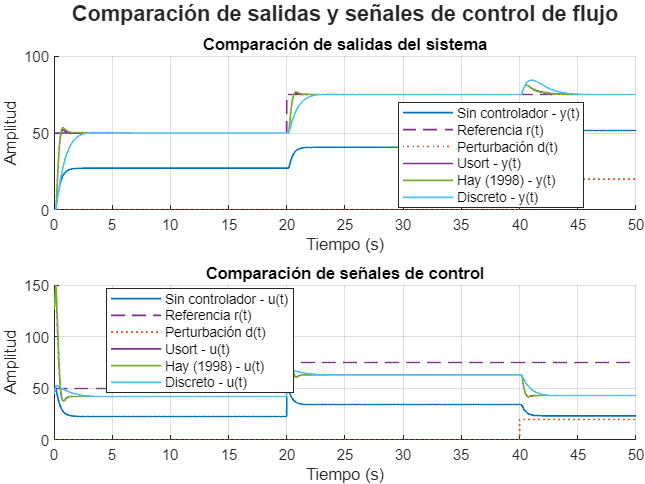

% Definir parámetros
planta_flujo = 'flujo';
controladores_flujo = {tf(1, 1), fluj_PIstandar_Usort, fluj_PIstandar_Hay, fluj_controladorDiscreto};
titulos_flujo = {'Sin controlador', 'Usort', 'Hay (1998)', 'Discreto'};
archivoSimulink = 'simulinkFluj.slx';
tiempoSimulacion_flujo = 50;

% Llamar a la función
comparacionControladoresServoRegulador(planta_flujo, controladores_flujo, titulos_flujo, archivoSimulink, tiempoSimulacion_flujo);

Controladores de temperatura

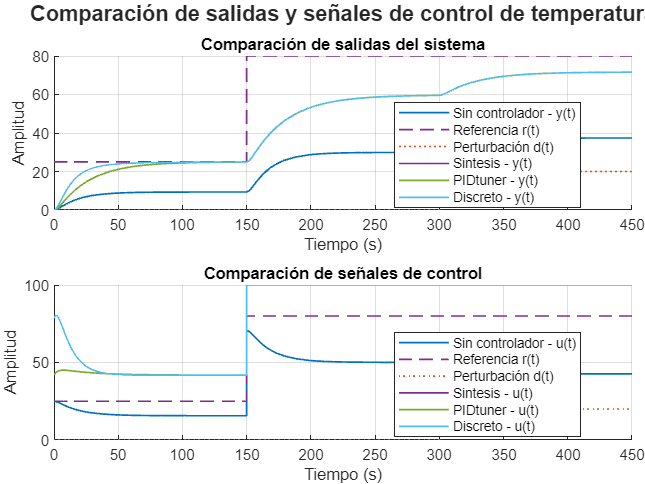


% Definir parámetros
planta_temperatura = 'temperatura';
controladores_temperatura = {tf(1, 1), temp_PIstandar_Sintesis, temp_PIstandar_Sintesis, temp_controladorDiscreto};
titulos_temperatura = {'Sin controlador', 'Sintesis', 'PIDtuner', 'Discreto'};
archivoSimulink_temperatura = 'simulinkTemp.slx';
tiempoSimulacion_temperatura = 450;

% Llamar a la función
comparacionControladoresServoRegulador(planta_temperatura, controladores_temperatura, titulos_temperatura, archivoSimulink_temperatura, tiempoSimulacion_temperatura);

## Análisis de datos reales

Datos de temperatura

    "Controlador: "    "Gráfica de respuesta del sistema de temperatura real 1."

  [Servo] Rango: [0, 668]
          Ta2 = 513, Mpn = 4.9057, IAE = 4850.95, Tvu = 176, Error permanente = 0.625
  [Regulador] Rango: [669, 772]
              Ta2 = 21, Mpn = 0.75758, IAE = 85.25, Tvu = 13, Error permanente = 1


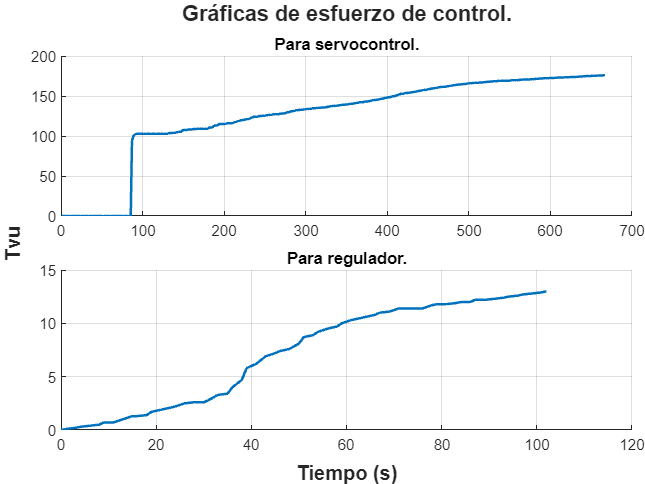

rangoServo_rt = [0, 668];
rangoRegulador_rt = [669, 772];
mostrar_datos_reales('RealesTemp_1.csv', 2, "Gráfica de respuesta del sistema de temperatura real 1.",true, rangoServo_rt, rangoRegulador_rt);

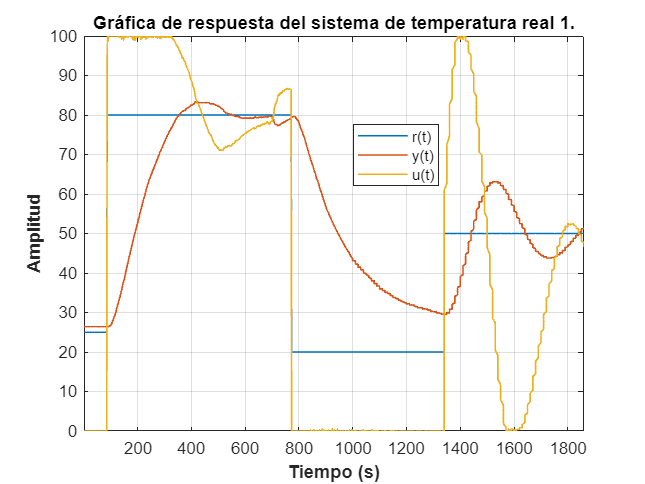

    "Controlador: "    "Gráfica de respuesta del sistema de temperatura real 2."

  [Servo] Rango: [801, 1399]
          Ta2 = NaN, Mpn = 177.7778, IAE = 10134.1, Tvu = 77.8262, Error permanente = 53
  [Regulador] Rango: [521, 714]
              Ta2 = 65, Mpn = 5.611, IAE = 408.9, Tvu = 49.6, Error permanente = 0.25


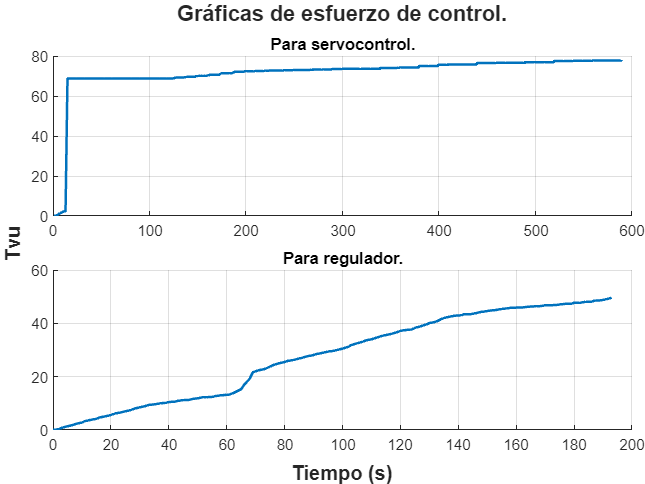

mostrar_datos_reales('RealesTemp_1.csv', 2, "Gráfica de respuesta del sistema de temperatura real 1.",false, rangoServo_rt, rangoRegulador_rt);
rangoServo_rt2 = [801, 1399];
rangoRegulador_rt2 = [521, 714];
mostrar_datos_reales('RealesTemp_2.csv', 2, "Gráfica de respuesta del sistema de temperatura real 2.",true,rangoServo_rt2, rangoRegulador_rt2);

mostrar_datos_reales('RealesTemp_2.csv', 2, "Gráfica de respuesta del sistema de temperatura real 2.",false,rangoServo_rt2, rangoRegulador_rt2);

Datos de flujo

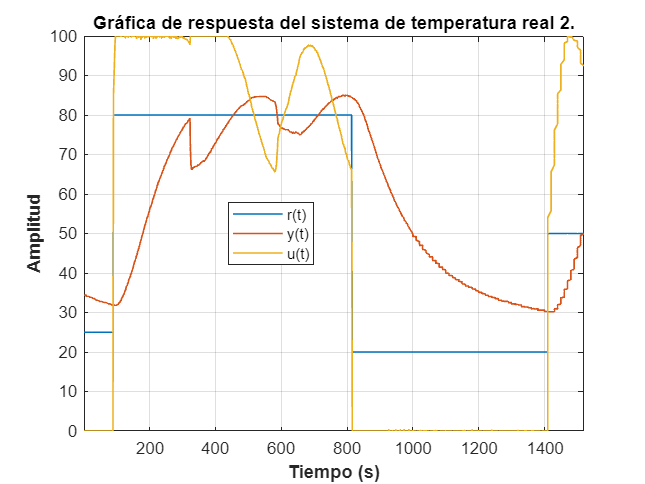

    "Controlador: "    "Gráfica de respuesta del sistema de flujo real."

  [Servo] Rango: [0, 337]
          Ta2 = 316.2956, Mpn = 2.6659, IAE = 6853.0495, Tvu = 55.6059, Error permanente = 0.46952
  [Regulador] Rango: [483, 530]
              Ta2 = 25.5575, Mpn = 28.1427, IAE = 2158.8766, Tvu = 55.1154, Error permanente = 0.44897


rangoServo_ft = [0, 337];
rangoRegulador_ft = [483, 530];
rangoRegulador_ft2 = [390, 411];
mostrar_datos_reales('Flujo_kp2.5177Ti0.9986_Eq1.7.txt.lvm', 9543, "Gráfica de respuesta del sistema de flujo real.",true,rangoServo_ft, rangoRegulador_ft);

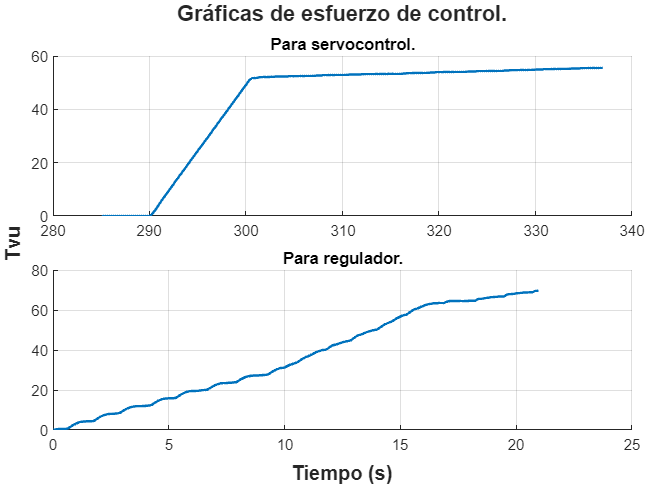

    "Controlador: "    "Gráfica de respuesta del sistema de flujo real pertubación grande."

  [Servo] Rango: [0, 337]
          Ta2 = 316.2956, Mpn = 2.6659, IAE = 6853.0495, Tvu = 55.6059, Error permanente = 0.46952
  [Regulador] Rango: [390, 411]
              Ta2 = NaN, Mpn = 23.2019, IAE = 15528.0631, Tvu = 69.6524, Error permanente = 36.3678


mostrar_datos_reales('Flujo_kp2.5177Ti0.9986_Eq1.7.txt.lvm', 9543, "Gráfica de respuesta del sistema de flujo real pertubación grande.",true,rangoServo_ft, rangoRegulador_ft2);

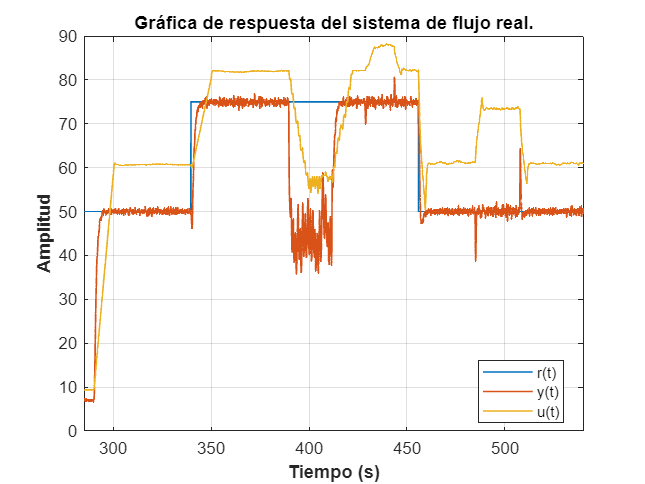

mostrar_datos_reales('Flujo_kp2.5177Ti0.9986_Eq1.7.txt.lvm', 9543, "Gráfica de respuesta del sistema de flujo real.",false,rangoServo_ft, rangoRegulador_ft);

## Especificaciones de diseño:

Temperatura

Controlador PI Sintesis:
  M_s = 1.0657
  Frecuencia asociada (rad/s) = 0.18821
Controlador PI Tuner:
  M_s = 1.1515
  Frecuencia asociada (rad/s) = 0.13811
Controlador Discreto:
  M_s = 1.1089
  Frecuencia asociada (rad/s) = 312.3911


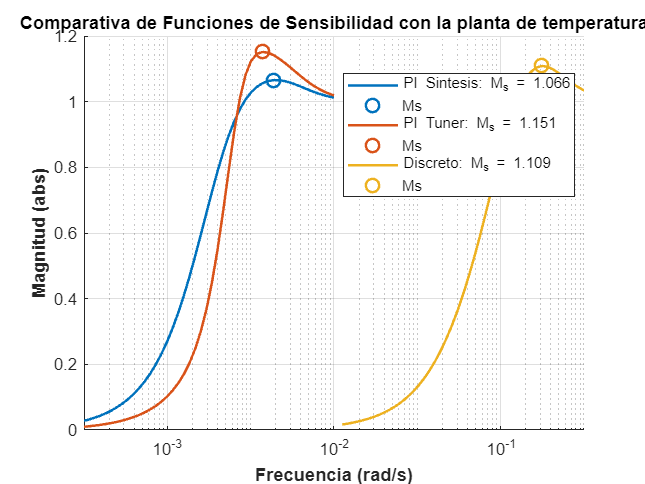

% Controladores
controladores_temp = {temp_PIstandar_Sintesis, temp_CtunPID, temp_controladorDiscreto};
nombres_temp = {'PI Sintesis', 'PI Tuner', 'Discreto'};

% Comparativa
calcular_y_graficar_sensibilidad(temp_G, ERPtemp, controladores_temp, nombres_temp,'temperatura', [0 1000]);

Controlador Discreto:
  M_s = 1.1089
  Frecuencia asociada (rad/s) = 312.3911


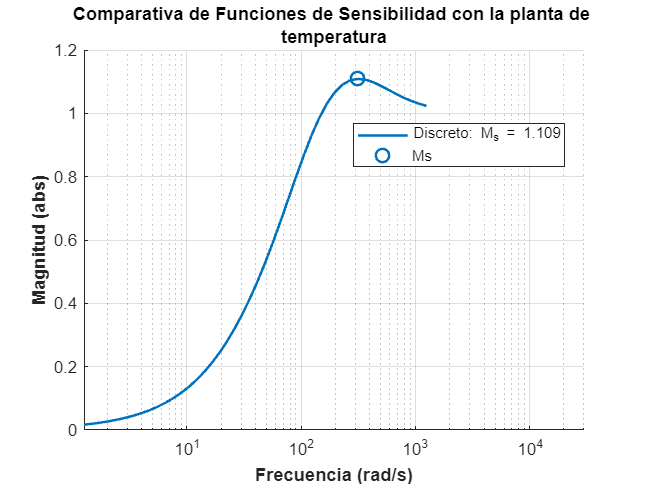

calcular_y_graficar_sensibilidad(temp_G, ERPtemp, {temp_controladorDiscreto}, {'Discreto'},{'temperatura'}, [0 30000]);

Flujo

Controlador PI Usort:
  M_s = 1.5935
  Frecuencia asociada (rad/s) = 6.8852
Controlador PI Hay(1998):
  M_s = 1.609
  Frecuencia asociada (rad/s) = 6.8063
Controlador Discreto:
  M_s = 1.1785
  Frecuencia asociada (rad/s) = 6087.5376


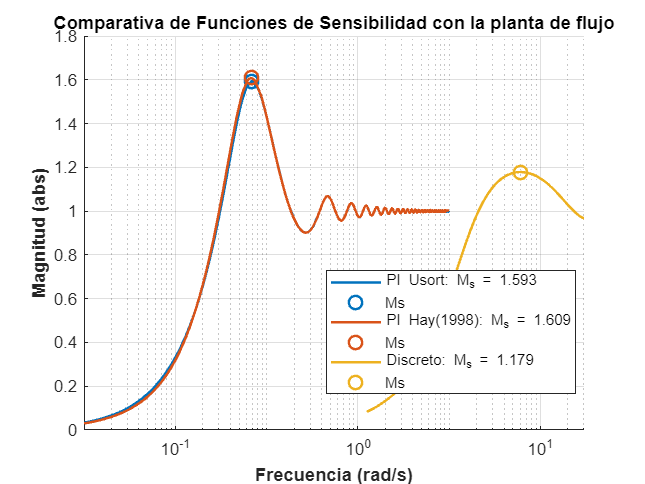

% Controladores
controladores_fluj = {fluj_PIstandar_Usort, fluj_PIstandar_Hay, fluj_controladorDiscreto};
nombres_fluj = {'PI Usort', 'PI Hay(1998)', 'Discreto'};

% Comparativa
calcular_y_graficar_sensibilidad(fluj_G, ERPfluj, controladores_fluj, nombres_fluj, 'flujo', [0 30000]);

Controlador Discreto:
  M_s = 1.1785
  Frecuencia asociada (rad/s) = 6087.5376


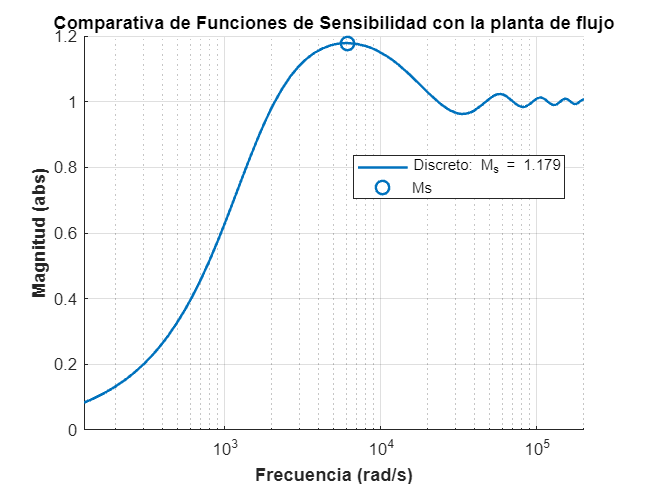

calcular_y_graficar_sensibilidad(fluj_G, ERPfluj, {fluj_controladorDiscreto}, {'Discreto'}, 'flujo', [0 200000]);

## Mostrar Métricas 

Controladores de flujo

% Ejes para gráficas de Tvu para flujo
graf_Tvu_flujo = tiledlayout(2, 1, 'TileSpacing', 'compact', 'Padding', 'tight');

% Subgráfica para servo
ax_servo_flujo = nexttile(graf_Tvu_flujo);
hold(ax_servo_flujo, 'on');
title(ax_servo_flujo, 'Para servocontrol.');
grid(ax_servo_flujo, 'on');
xlim(ax_servo_flujo, [0 4]);
legend(ax_servo_flujo);

% Subgráfica para regulador
ax_regulador_flujo = nexttile(graf_Tvu_flujo);
hold(ax_regulador_flujo, 'on');
title(ax_regulador_flujo, 'Para regulador.');
grid(ax_regulador_flujo, 'on');
xlim(ax_regulador_flujo, [0 4]);
legend(ax_regulador_flujo);

sgtitle(graf_Tvu_flujo, 'Gráficas de esfuerzo de controladores de flujo.', 'FontWeight', 'bold');
xlabel(graf_Tvu_flujo, 'Tiempo (s)', 'FontWeight', 'bold')
ylabel(graf_Tvu_flujo, 'Tvu', 'FontWeight', 'bold')


disp(['-----------------------------' ...
    'Métricas del proceso de flujo' ...
    '-------------------------------'])

-----------------------------Métricas del proceso de flujo-------------------------------


rangoServo = [0, 19];
rangoRegulador = [41, 50];
mostrar_simulacion(tf(1, 1), 50, 'simulinkFluj.slx', 'Sin controlador', [ax_servo_flujo, ax_regulador_flujo], 1, rangoServo, rangoRegulador)

Controlador: Sin controlador
  [Servo] Rango: [0, 19]
          Ta2 = NaN, Mpn = 0, IAE = 448072.7625, Tvu = 27.171, Error permanente = 45.6579
  [Regulador] Rango: [41, 50]
              Ta2 = NaN, Mpn = 0, IAE = 210707.4214, Tvu = 0.99189, Error permanente = 31.1667


mostrar_simulacion(fluj_PIstandar_Usort, 50, 'simulinkFluj.slx', 'Usort', [ax_servo_flujo, ax_regulador_flujo], 1, rangoServo, rangoRegulador)

Controlador: Usort
  [Servo] Rango: [0, 19]
          Ta2 = 0.987, Mpn = 3.9707, IAE = 17969.1699, Tvu = 134.4281, Error permanente = 3.1541e-09
  [Regulador] Rango: [41, 50]
              Ta2 = 0.995, Mpn = 5.6213, IAE = 4064.9403, Tvu = 0.4863, Error permanente = 0.00068042


mostrar_simulacion(fluj_PIstandar_Hay, 50, 'simulinkFluj.slx', 'Hay (1998)', [ax_servo_flujo, ax_regulador_flujo], 1, rangoServo, rangoRegulador)

Controlador: Hay (1998)
  [Servo] Rango: [0, 19]
          Ta2 = 1.21, Mpn = 6.8036, IAE = 19084.5826, Tvu = 139.3556, Error permanente = 1.5497e-09
  [Regulador] Rango: [41, 50]
              Ta2 = 0.797, Mpn = 5.3488, IAE = 3282.2946, Tvu = 0.8709, Error permanente = 0.00014085


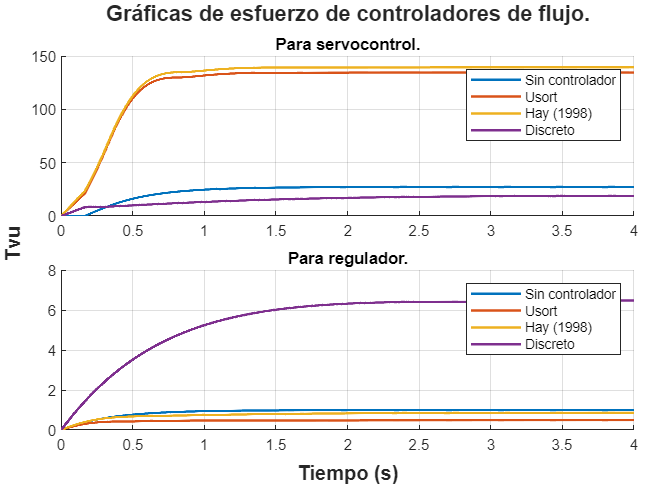

Controlador: Discreto
  [Servo] Rango: [0, 19]
          Ta2 = 3.745, Mpn = 0.64583, IAE = 42909.6484, Tvu = 19.1502, Error permanente = 3.1043e-08
  [Regulador] Rango: [41, 50]
              Ta2 = 2.507, Mpn = 12.4834, IAE = 14430.6599, Tvu = 6.5442, Error permanente = 0.0010658


mostrar_simulacion(fluj_controladorDiscreto, 50, 'simulinkFluj.slx', 'Discreto', [ax_servo_flujo, ax_regulador_flujo], 1, rangoServo, rangoRegulador)

Controladores de temperatura

% Ejes para gráficas de Tvu para flujo
graf_Tvu_temp = tiledlayout(2, 1, 'TileSpacing', 'compact', 'Padding', 'tight');

% Subgráfica para servo
ax_servo_temp = nexttile(graf_Tvu_temp);
hold(ax_servo_temp, 'on');
title(ax_servo_temp, 'Para servocontrol.');
grid(ax_servo_temp, 'on');
xlim(ax_servo_temp, [0 100]);
legend(ax_servo_temp);

% Subgráfica para regulador
ax_regulador_temp = nexttile(graf_Tvu_temp);
hold(ax_regulador_temp, 'on');
title(ax_regulador_temp, 'Para regulador.');
grid(ax_regulador_temp, 'on');
xlim(ax_regulador_temp, [0 100]);
legend(ax_regulador_temp);

sgtitle(graf_Tvu_temp, 'Gráficas de esfuerzo de controladores de temperatura.', 'FontWeight', 'bold');
xlabel(graf_Tvu_temp, 'Tiempo (s)', 'FontWeight', 'bold')
ylabel(graf_Tvu_temp, 'Tvu', 'FontWeight', 'bold')


disp(['-----------------------------' ...
    'Métricas del proceso de temperatura' ...
    '-------------------------------'])

-----------------------------Métricas del proceso de temperatura-------------------------------


rangoServo = [0, 149];
rangoRegulador = [301, 450];
mostrar_simulacion(tf(1, 1), 450, 'simulinkTemp.slx', 'Sin controlador', [ax_servo_temp, ax_regulador_temp], 1, rangoServo, rangoRegulador)

Controlador: Sin controlador
  [Servo] Rango: [0, 149]
          Ta2 = NaN, Mpn = 0, IAE = 603.1423, Tvu = 9.346, Error permanente = 62.6158
  [Regulador] Rango: [301, 450]
              Ta2 = NaN, Mpn = 0, IAE = 927.4339, Tvu = 7.2181, Error permanente = 53.264


mostrar_simulacion(temp_PIstandar_Sintesis, 450, 'simulinkTemp.slx', 'Síntesis', [ax_servo_temp, ax_regulador_temp], 1, rangoServo, rangoRegulador)

Controlador: Síntesis
  [Servo] Rango: [0, 149]
          Ta2 = 142.8664, Mpn = 0, IAE = 401.6068, Tvu = 6.4493, Error permanente = 0.37754
  [Regulador] Rango: [301, 450]
              Ta2 = NaN, Mpn = 0, IAE = 247.6001, Tvu = 0, Error permanente = 10.5001


mostrar_simulacion(temp_CtunPID, 450, 'simulinkTemp.slx', 'PIDtuner', [ax_servo_temp, ax_regulador_temp],1, rangoServo, rangoRegulador)

Controlador: PIDtuner
  [Servo] Rango: [0, 149]
          Ta2 = 86.6736, Mpn = 9.4379, IAE = 359.4494, Tvu = 45.409, Error permanente = 0.16253
  [Regulador] Rango: [301, 450]
              Ta2 = NaN, Mpn = 0, IAE = 245.2605, Tvu = 0, Error permanente = 10.5


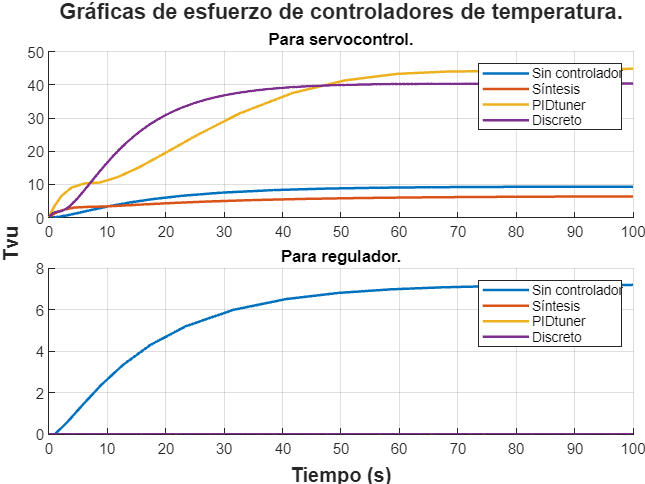

Controlador: Discreto
  [Servo] Rango: [0, 149]
          Ta2 = 149, Mpn = 0, IAE = 83540.4252, Tvu = 40.4049, Error permanente = 0.1744
  [Regulador] Rango: [301, 450]
              Ta2 = NaN, Mpn = 0, IAE = 319506.3413, Tvu = 0, Error permanente = 10.5003


mostrar_simulacion(temp_controladorDiscreto, 450, 'simulinkTemp.slx', 'Discreto', [ax_servo_temp, ax_regulador_temp],1, rangoServo, rangoRegulador)

## Funciones de generación de figuras

Simulaciones de controlador

function mostrar_simulacion(controlador, tiempoSimulacion, archivoSimul, titulo, AxesHandle, mostrarMetricas, rangoServo, rangoRegulador)
    % Si AxesHandle no es proporcionado, asignar [] por defecto
    if nargin < 5
        AxesHandle = [];
    end    
    % Asignar el controlador y simular
    assignin('base', 'controladorPID', controlador);
    sim_result = sim(archivoSimul, tiempoSimulacion);

    % Extraer datos
    tiempo = sim_result.tout;
    datosControlados = sim_result.Controlado.Data;
    y_t = datosControlados(:, 4);  % Salida y(t)
    u_t = datosControlados(:, 2);
    r_t = datosControlados(:, 1);  % Referencia

    if mostrarMetricas == 1
        % Filtrar los datos según los rangos de tiempo
        [t_servo, r_servo, y_servo, u_servo] = filtrar_datos(tiempo, r_t, y_t,  u_t, rangoServo);
        [t_reg, r_reg, y_reg, u_reg] = filtrar_datos(tiempo, r_t, y_t,  u_t, rangoRegulador);
    
        % Calcular métricas para el modo servo
        Ta2_servo = calcular_Ta2(t_servo, r_servo, y_servo);
        Mpn_servo = calcular_Mpn(y_servo);  
        IAE_servo = calcular_IAE(r_servo, y_servo); 
        [Tvu_servo, vectorTvu_servo] = calcular_Tvu(u_servo);
        errp_servo = calcular_errp(t_servo, y_servo, r_servo); % Error permanente
    
        % Calcular métricas para el modo regulador
        Ta2_reg = calcular_Ta2(t_reg, r_reg, y_reg); 
        Mpn_reg = calcular_Mpn(y_reg);       
        IAE_regulador = calcular_IAE(r_reg, y_reg); 
        [Tvu_regulador, vectorTvu_regulador] = calcular_Tvu(u_reg); 
        errp_reg = calcular_errp(t_reg, y_reg, r_reg); % Error permanente
    
        % Mostrar métricas en la consola
        disp(['Controlador: ', titulo]);
        disp(['  [Servo] Rango: [', num2str(rangoServo(1)), ', ', num2str(rangoServo(2)), ']']);
        disp(['          Ta2 = ', num2str(Ta2_servo), ', Mpn = ', num2str(Mpn_servo), ...
              ', IAE = ', num2str(IAE_servo), ', Tvu = ', num2str(Tvu_servo), ...
              ', Error permanente = ', num2str(errp_servo)]);
        disp(['  [Regulador] Rango: [', num2str(rangoRegulador(1)), ', ', num2str(rangoRegulador(2)), ']']);
        disp(['              Ta2 = ', num2str(Ta2_reg), ', Mpn = ', num2str(Mpn_reg), ...
              ', IAE = ', num2str(IAE_regulador), ', Tvu = ', num2str(Tvu_regulador), ...
              ', Error permanente = ', num2str(errp_reg)]);

        % Graficar Tvu
        ax_servo = AxesHandle(1);
        ax_regulador = AxesHandle(2);
        plot(ax_servo, t_servo, vectorTvu_servo, 'DisplayName', titulo, 'LineWidth', 1.5)
        plot(ax_regulador, t_reg, vectorTvu_regulador, 'DisplayName', titulo, 'LineWidth', 1.5)

    else
        % Graficar resultados cuando no solo se quieren las métricas
        plot(AxesHandle, tiempo, y_t, 'Color', '#0072BD', 'DisplayName', 'y(t)', "LineWidth", 1);
        hold(AxesHandle, 'on');
        grid(AxesHandle, 'on');
        plot(AxesHandle, tiempo, r_t, 'Color', '#EDB120', 'DisplayName', 'r(t)', "LineWidth", 1);
        plot(AxesHandle, tiempo, datosControlados(:, 2), 'Color', '#7E2F8E', 'DisplayName', 'u(t)', "LineWidth", 1);
        plot(AxesHandle, tiempo, datosControlados(:, 3), 'Color', '#D95319', 'DisplayName', 'd(t)', "LineWidth", 1);

        title(AxesHandle, titulo, 'FontWeight', 'bold');

        % Una sola leyenda para los 4
        if strcmp(titulo, 'Sin controlador')
            legend(AxesHandle, 'Location', 'best');
        end    
        hold(AxesHandle, 'off');
    end
end


function [t_filt, r_filt, y_filt, u_filt] = filtrar_datos(t, r, y, u, rango)
    % Filtrar datos en un rango de tiempo específico
    idx = t >= rango(1) & t <= rango(2);
    t_filt = t(idx) - rango(1);  % Normalizar tiempo al inicio del rango
    r_filt = r(idx);
    y_filt = y(idx);
    u_filt = u(idx);
end

function Ta2 = calcular_Ta2(tiempo, r_t, y_t)
    % Calcular el tiempo de establecimiento al 2% (relativo al inicio del tiempo)
    
    final_value = r_t(end);           % Valor final de la referencia
    threshold = 0.02 * final_value;   % Tolerancia del 2% del valor final
    
    % Encontrar el índice del pico máximo (Mpn) en y_t
    [~, idx_peak] = max(y_t); 

    % Evaluar el tiempo de establecimiento solo después del pico máximo
    for i = idx_peak:length(y_t)
        % Verificar si la salida está dentro del rango del 2% de la referencia
        if abs(y_t(i) - final_value) <= threshold
            Ta2 = tiempo(i); % Escala relativa al inicio
            return;
        end
    end

    Ta2 = NaN;  % Si no se cumple el criterio, devolver NaN
end



function Mpn = calcular_Mpn(y_t)
    % Calcular sobrepico como porcentaje de la referencia final
    peak_value = max(y_t);  % Valor máximo de la salida
    final_value = y_t(end); % Valor final de la referencia
    Mpn = ((peak_value - final_value) / final_value) * 100;
    if Mpn<0
        Mpn = 0;
        return;
    end
end

function IAE = calcular_IAE(r_t, y_t)
    % Calcular el índice integral del error absoluto (IAE)
    IAE = trapz(abs(r_t - y_t)); % Integral del error absoluto
end

function [Tvu, vectorTvu] = calcular_Tvu(u_t)
    % Cálculo de la variación total del esfuerzo de control (TV_u)
    % tiempo: vector de tiempo
    % u_t: vector de esfuerzo de control

    % Asegurar que u_t es un vector columna
    if size(u_t, 1) == 1
        u_t = u_t';
    end

    % Calcular las diferencias absolutas entre pasos sucesivos
    delta_u = abs(diff(u_t));

    % Sumar las diferencias (variación total del control)
    Tvu = sum(delta_u);

    % Calcular vector de Tvu acumulativo
    vectorTvu = [0; cumsum(delta_u)];
end

function errp = calcular_errp(tiempo, y_t, r_t)
    % Calcular el error permanente (error de estado estacionario)
    % tiempo: vector de tiempo
    % y_t: salida del sistema
    % r_t: referencia

    % Asegurarse de que el tiempo no está vacío
    if isempty(tiempo)
        errp = NaN;
        return;
    end

    % Extraer los valores finales de la referencia y la salida
    y_final = y_t(end); % Último valor de la salida
    r_final = r_t(end); % Último valor de la referencia

    % Calcular el error permanente como la diferencia entre referencia y salida
    errp = abs(((r_final - y_final)/r_final)*100);
end

Comparar controladores

function comparacionControladoresServoRegulador(tipoPlanta, controladores, titulos, archivoSimulink, tiempoSimulacion)
    % comparacionControladoresServoRegulador
    % Esta función compara los controladores servo y regulador en un sistema de temperatura o flujo.
    %
    % Parámetros:
    % - tipoPlanta: cadena indicando el tipo de planta ('temperatura' o 'flujo').
    % - controladores: celda con los controladores a evaluar.
    % - titulos: celda con los nombres asociados a cada controlador.
    % - archivoSimulink: nombre del archivo de Simulink a utilizar.
    % - tiempoSimulacion: duración de la simulación en segundos.

    % Validar tipoPlanta
    if ~ismember(tipoPlanta, {'temperatura', 'flujo'})
        error("El parámetro 'tipoPlanta' debe ser 'temperatura' o 'flujo'.");
    end

    % Configuración del tiledlayout para la comparación
    comparacion_general = tiledlayout(2, 1, 'TileSpacing', 'compact', 'Padding', 'tight');
    
    % Subgráfica para las salidas del sistema
    ax_salidas = nexttile(comparacion_general);
    hold(ax_salidas, 'on');
    title(ax_salidas, 'Comparación de salidas del sistema');
    xlabel(ax_salidas, 'Tiempo (s)');
    ylabel(ax_salidas, 'Amplitud');
    grid(ax_salidas, 'on');

    % Subgráfica para las señales de control
    ax_control = nexttile(comparacion_general);
    hold(ax_control, 'on');
    title(ax_control, 'Comparación de señales de control');
    xlabel(ax_control, 'Tiempo (s)');
    ylabel(ax_control, 'Amplitud');
    grid(ax_control, 'on');
    
    % Simulaciones y gráficos
    for i = 1:length(controladores)
        % Asignar el controlador actual a la base de Simulink
        controlador = controladores{i};
        titulo = titulos{i};
        assignin('base', 'controladorPID', controlador);

        % Ejecutar simulación
        sim_result = sim(archivoSimulink, tiempoSimulacion);

        % Extraer datos
        tiempo = sim_result.tout;
        datosControlados = sim_result.Controlado.Data;
        y_t = datosControlados(:, 4);  % Salida y(t)
        u_t = datosControlados(:, 2);  % Señal de control u(t)
        d_t = datosControlados(:, 3);  % Perturbación d(t)
        r_t = datosControlados(:, 1);  % Referencia r(t)

        % Graficar en la subgráfica de salidas
        plot(ax_salidas, tiempo, y_t, 'DisplayName', [titulo, ' - y(t)'], "LineWidth", 1);
        if i == 1
            % La referencia y la perturbación solo se grafican una vez
            plot(ax_salidas, tiempo, r_t, 'DisplayName', 'Referencia r(t)', 'LineStyle', '--', "LineWidth", 1, 'Color', '#7E2F8E');
            plot(ax_salidas, tiempo, d_t, 'DisplayName', 'Perturbación d(t)', 'LineStyle', ':', "LineWidth", 1, 'Color', '#D95319');
        end

        % Graficar en la subgráfica de señales de control
        plot(ax_control, tiempo, u_t, 'DisplayName', [titulo, ' - u(t)'], "LineWidth", 1);
        if i == 1
            % La referencia y la perturbación solo se grafican una vez aquí también
            plot(ax_control, tiempo, r_t, 'DisplayName', 'Referencia r(t)', 'LineStyle', '--', "LineWidth", 1, 'Color', '#7E2F8E');
            plot(ax_control, tiempo, d_t, 'DisplayName', 'Perturbación d(t)', 'LineStyle', ':', "LineWidth", 1, 'Color', '#D95319');
        end
    end

    % Añadir leyendas
    legend(ax_salidas, 'Location', 'best');
    legend(ax_control, 'Location', 'best');

    % Agregar título general personalizado
    sgtitle(comparacion_general, ['Comparación de salidas y señales de control de ', tipoPlanta], 'FontWeight', 'bold');
end



Datos reales

function mostrar_datos_reales(archivoCSV, inicioFigura, titulo, mostrarMetricas, rangoServo, rangoRegulador)
    % Leer el archivo CSV y determinar índices de columnas
    if strcmp(archivoCSV, 'Flujo_kp2.5177Ti0.9986_Eq1.7.txt.lvm')
        datosReales = readmatrix(archivoCSV, Delimiter = '\t', DecimalSeparator=',', FileType='text');
        indices = [1 2 3 4];
    else
        datosReales = readmatrix(archivoCSV);
        indices = [1 6 4 2];
    end

    % Extraer datos
    t_real = datosReales(inicioFigura:end, indices(1));
    r_real = datosReales(inicioFigura:end, indices(2));
    y_real = datosReales(inicioFigura:end, indices(3));
    u_real = datosReales(inicioFigura:end, indices(4));
    
    if mostrarMetricas
        % Filtrar datos para los modos servo y regulador
        [t_servo, r_servo, y_servo, u_servo] = filtrar_datos(t_real, r_real, y_real, u_real, rangoServo);
        [t_reg, r_reg, y_reg, u_reg] = filtrar_datos(t_real, r_real, y_real, u_real, rangoRegulador);
        
        % Calcular métricas para el modo servo
        Ta2_servo = calcular_Ta2(t_servo, r_servo, y_servo);
        Mpn_servo = calcular_Mpn(y_servo);  
        IAE_servo = calcular_IAE(r_servo, y_servo); 
        [Tvu_servo, vectorTvu_servo] = calcular_Tvu(u_servo);
        errp_servo = calcular_errp(t_servo, y_servo, r_servo); % Error permanente
    
        % Calcular métricas para el modo regulador
        Ta2_reg = calcular_Ta2(t_reg, r_reg, y_reg); 
        Mpn_reg = calcular_Mpn(y_reg);       
        IAE_regulador = calcular_IAE(r_reg, y_reg); 
        [Tvu_regulador, vectorTvu_regulador] = calcular_Tvu(u_reg); 
        errp_reg = calcular_errp(t_reg, y_reg, r_reg); % Error permanente
    
        % Mostrar métricas en la consola
        disp(['Controlador: ', titulo]);
        disp(['  [Servo] Rango: [', num2str(rangoServo(1)), ', ', num2str(rangoServo(2)), ']']);
        disp(['          Ta2 = ', num2str(Ta2_servo), ', Mpn = ', num2str(Mpn_servo), ...
              ', IAE = ', num2str(IAE_servo), ', Tvu = ', num2str(Tvu_servo), ...
              ', Error permanente = ', num2str(errp_servo)]);
        disp(['  [Regulador] Rango: [', num2str(rangoRegulador(1)), ', ', num2str(rangoRegulador(2)), ']']);
        disp(['              Ta2 = ', num2str(Ta2_reg), ', Mpn = ', num2str(Mpn_reg), ...
              ', IAE = ', num2str(IAE_regulador), ', Tvu = ', num2str(Tvu_regulador), ...
              ', Error permanente = ', num2str(errp_reg)]);

        % Graficar Tvu
        graf_Tvu = tiledlayout(2, 1, 'TileSpacing', 'compact', 'Padding', 'tight');
    
        % Subgráfica para servo
        ax_servo = nexttile(graf_Tvu);
        hold(ax_servo, 'on');
        title(ax_servo, 'Para servocontrol.');
        grid(ax_servo, 'on');
        plot(ax_servo, t_servo, vectorTvu_servo, 'LineWidth', 1.5)
    
        % Subgráfica para regulador
        ax_regulador = nexttile(graf_Tvu);
        hold(ax_regulador, 'on');
        title(ax_regulador, 'Para regulador.');
        grid(ax_regulador, 'on');
        plot(ax_regulador, t_reg, vectorTvu_regulador, 'LineWidth', 1.5)
        
        sgtitle(graf_Tvu, 'Gráficas de esfuerzo de control.', 'FontWeight', 'bold');
        xlabel(graf_Tvu, 'Tiempo (s)', 'FontWeight', 'bold')
        ylabel(graf_Tvu, 'Tvu', 'FontWeight', 'bold')

        hold off;

    else
        % Graficar datos reales
        figure;
        plot(t_real, r_real, 'DisplayName', 'r(t)', "LineWidth", 1);
        hold on;
        plot(t_real, y_real, 'DisplayName', 'y(t)', "LineWidth", 1);
        plot(t_real, u_real, 'DisplayName', 'u(t)', "LineWidth", 1);

        % Personalización de la gráfica
        grid on;
        title(titulo, 'FontWeight', 'bold');
        xlabel("Tiempo (s)", 'FontWeight', 'bold');
        ylabel("Amplitud", 'FontWeight', 'bold');
        legend('Location', 'best');
        xlim([min(t_real) max(t_real)]);
        
        hold off;
    end
end



Función para calcular M_S

function calcular_y_graficar_sensibilidad(planta_continua, planta_discreta, controladores, nombres_controladores, nombre_planta, x_lim)
    % planta_continua: modelo de transferencia de la planta continua
    % planta_discreta: modelo de transferencia de la planta discreta
    % controladores: celda con modelos de transferencia de los controladores
    % nombres_controladores: celda con los nombres de los controladores
    % nombre_planta: nombre descriptivo de la planta (e.g., 'flujo', 'temperatura')
    % x_lim: (opcional) límites del eje x en formato [xmin xmax]

    % Validar que controladores y nombres coincidan
    if length(controladores) ~= length(nombres_controladores)
        error('El número de controladores y nombres no coincide.');
    end

    if nargin < 6 || isempty(x_lim)
        x_lim = [1e-2, 1e4]; % Valores por defecto
    elseif length(x_lim) ~= 2 || x_lim(1) >= x_lim(2)
        error('El argumento x_lim debe ser un vector [xmin xmax] con xmin < xmax.');
    end

    colores = lines(length(controladores));
    figure;
    hold on;

    for i = 1:length(controladores)
        if isdt(controladores{i})
            planta = planta_discreta;
        else
            planta = planta_continua;
        end

        % Convertir sistemas discretos a espacio de estados
        if isdt(controladores{i}) || isdt(planta)
            controlador = ss(controladores{i});
            planta = ss(planta);
        else
            controlador = controladores{i};
        end

        [Ms, w_Ms, w, mag] = calcular_sensibilidad(planta, controlador, nombres_controladores{i});
        
        % Corregir la representación de frecuencias discretas
        if isdt(controladores{i})
            w(w < x_lim(1)) = x_lim(1); % Forzar que inicien en el límite inferior
        end

        semilogx(w, mag, 'Color', colores(i, :), 'LineWidth', 1.5, ...
                 'DisplayName', [nombres_controladores{i}, ': M_s = ', num2str(Ms, '%.3f')]);
        semilogx(w_Ms, Ms, 'o', 'Color', colores(i, :), 'MarkerSize', 8, 'LineWidth', 1.5, 'DisplayName', 'Ms');
    end

    xlabel('Frecuencia (rad/s)', 'FontWeight', 'bold');
    ylabel('Magnitud (abs)', 'FontWeight', 'bold');
    xlim(x_lim);
    title(['Comparativa de Funciones de Sensibilidad con la planta de ', nombre_planta], 'FontWeight', 'bold');
    legend('Location', 'Best');
    grid on;

    ax = gca;
    ax.XScale = 'log';
    ax.XTickLabel = arrayfun(@(x) sprintf('10^{%d}', log10(x)), ax.XTick, 'UniformOutput', false);

    hold off;
end

function [Ms, w_Ms, w, mag] = calcular_sensibilidad(planta, controlador, nombre_controlador)
    % Calcula la función de sensibilidad S(s) o S(z) dependiendo del tipo de controlador
    if isdt(controlador) || isdt(planta)
        % Controlador y/o planta discretos
        Ts = planta.Ts;
        if Ts <= 0
            error('La planta discreta no tiene un tiempo de muestreo válido.');
        end
        S = tf(1, 1, Ts) / (1 + controlador * planta);
        
        % Frecuencia normalizada y magnitud
        [mag, ~, w_n] = bode(S);
        mag = squeeze(mag);
        
        % Convertir frecuencia normalizada a rad/s
        w = w_n * (2 * pi / Ts);
    else
        % Controlador y planta continuos
        S = tf(1, 1) / (1 + controlador * planta);
        
        % Magnitud y frecuencias
        [mag, ~, w] = bode(S);
        mag = squeeze(mag);
    end

    % Sensibilidad máxima
    [Ms, ind_Ms] = max(mag);
    w_Ms = w(ind_Ms);

    % Mostrar resultados en consola
    disp(['Controlador ', nombre_controlador, ':']);
    disp(['  M_s = ', num2str(Ms)]);
    disp(['  Frecuencia asociada (rad/s) = ', num2str(w_Ms)]);
end
